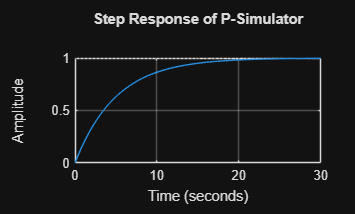

clc;
clear;
close all;

% P-Simulator (First Order Process)

K = 1;          % Process gain
tau = 5;        % Time constant

num = K;
den = [tau 1];

P_sys = tf(num,den);

figure;
step(P_sys);
grid on;
title('Step Response of P-Simulator');

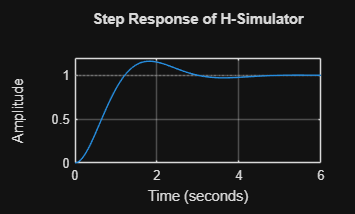

% H-Simulator (Second Order Hydraulic System)

K = 1;
wn = 2;
zeta = 0.5;

num = K*wn^2;
den = [1 2*zeta*wn wn^2];

H_sys = tf(num,den);

figure;
step(H_sys);
grid on;
title('Step Response of H-Simulator');

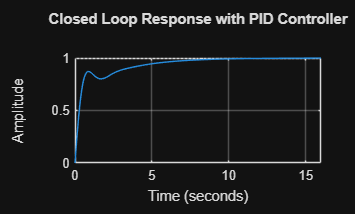

% PID Controller

Kp = 2;
Ki = 1;
Kd = 0.5;

PID = pid(Kp,Ki,Kd);

% Closed Loop System
CL_sys = feedback(PID*H_sys,1);

figure;
step(CL_sys);
grid on;
title('Closed Loop Response with PID Controller');